## Deducción del Método de Simpson para Superficie de Revolución Mínima

### Método de Simpson

#### Discretización

Para aplicar el método de Simpson 1/3, dividimos el intervalo [0,1] en n subintervalos de igual longitud h = 1/n. La fórmula de Simpson para aproximar la integral es:


$$$$ A \approx \frac{b-a}{6n} \sum_{j=0}^{n-2} [f_j + 4f_{j+1} + f_{j+2}] $$$$


o si mantenemos la notación original:


$$$$ I(u) \approx \sum_{j=0}^{n-2} S_{j}(u)$$$$


Donde:

$$$S_{j}(u):$$$ es el área calculada por método de Simpson en el intervalo $$$[u_{j}, u_{j+2}]$$$ 

y,


$$$$ f_j = u(x_j)\sqrt{1 + n^2\left(u(x_{j+1}) - u(x_j)})^2} $$$$


#### Aproximación Discreta

En forma discreta, para cada subintervalo:


$$$$ S_j = \frac{1}{6n}[u_j\sqrt{1 + n^2(u_{j+1} - u_j)^2} + 4u_{j+1}\sqrt{1 + n^2(u_{j+2} - u_{j+1})^2} + u_{j+2}\sqrt{1 + n^2(u_{j+2} - u_{j+1})^2}] $$$$


#### Cálculo del Gradiente

Para minimizar el área, necesitamos calcular el gradiente con respecto a cada punto $$u_k$$. La derivada parcial con respecto a $$u_k$$ implica considerar todos los términos $$S_j$$ que contienen $$u_k$$.

Así, para un punto interior$ $u_k$,$ el gradiente cuenta con tres componentes:

1. Con respecto a $u_j$:


$$\frac{1}{6n}\left[\sqrt{1 + n^2(u_{j+1} - u_j)^2} - \frac{u_jn^2(u_{j+1} - u_j)}{\sqrt{1 + n^2(u_{j+1} - u_j)^2}}\right]$$


2. con respecto a $u_{j+1}$


$$\frac{1}{6n}\left[u_j\frac{n^2(u_{j+1} - u_j)}{\sqrt{1 + n^2(u_{j+1} - u_j)^2}} + 4\sqrt{1 + n^2(u_{j+2} - u_{j+1})^2} - \frac{4u_{j+1}n^2(u_{j+2} - u_{j+1})}{\sqrt{1 + n^2(u_{j+2} - u_{j+1})^2}}\right]$$


3. Con respecto a $u_{j+2}$


$$ \frac{1}{6n}\left[\frac{4u_{j+1}n^2(u_{j+2} - u_{j+1})}{\sqrt{1 + n^2(u_{j+2} - u_{j+1})^2}} + \sqrt{1 + n^2(u_{j+2} - u_{j+1})^2} + \frac{u_{j+2}n^2(u_{j+2} - u_{j+1})}{\sqrt{1 + n^2(u_{j+2} - u_{j+1})^2}}\right]$$


Combinando estos términos, el gradiente para un punto interior $$u_k$$ es:


$$$$ \nabla_k = \frac{\partial S_{k-2}}{\partial u_k} + \frac{\partial S_{k-1}}{\partial u_k} + \frac{\partial S_k}{\partial u_k} $$$$


El vector gradiente $$\nabla F \in \mathbb{R}^{n+1}$$ tiene la siguiente estructura:


$$$$ \nabla F = \left( \begin{array}{cccccc} g_0 & g_1 & g_2 & \cdots & g_{n-1} & g_n \end{array} \right) $$$$


donde cada componente se define como:

Para $$k = 0$$ (primer punto): 


$$$$ g_0 = \frac{1}{6n}\left(\sqrt{1 + n^2(u_1 - u_0)^2} - \frac{u_0n^2(u_1 - u_0)}\sqrt{1 + n^2(u_1 - u_0)^2}\right) $$$$


Para $$k = 1,2,\ldots,n-1$ (puntos interiores)$: 


$$g_{k} = \frac{1}{6n}\sum_{k=1}^{n-1}\left[\sqrt{1+n^2(u_{k+1}-u_j)^2} + 5\sqrt{1+n^2(u_{k+2}-u_{k+1})^2} \right. \\
+ n^2(u_{k+2}-u_{k+1})\frac{u_{k+2}}{\sqrt{1+n^2(u_{k+2}-u_{k+1})^2}} \\
\left. + n^2(u_{k+1}-u_j)\frac{-u_j}{\sqrt{1+n^2(u_{k+1}-u_j)^2}}\right]$$


Para $$k = n$$ (último punto):


$$ $$ g_n = \frac{1}{6n}\left(\sqrt{1 + n^2(u_n - u_{n-1})^2} + \frac_{4u_{n-1}n^2(u_n - u_{n-1})}\sqrt{1 + n^2(u_n - u_{n-1})^2}\right) $$
$$


### **BENCHMARK**

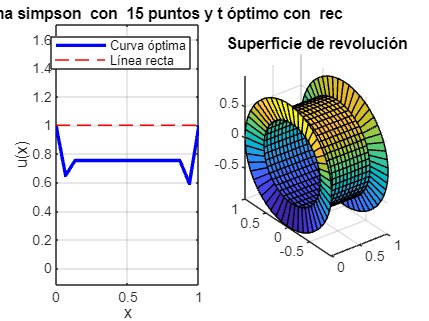

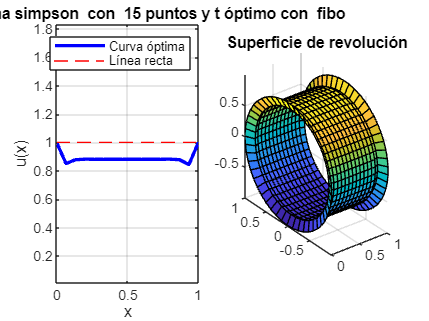

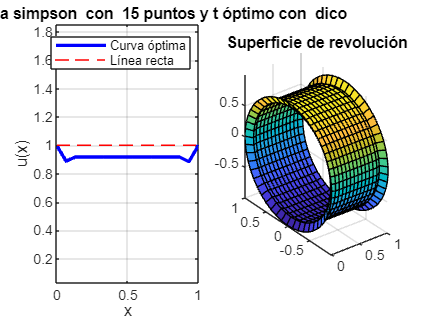

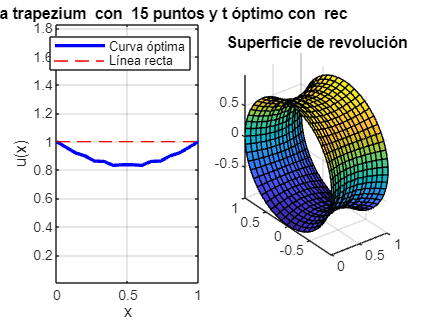

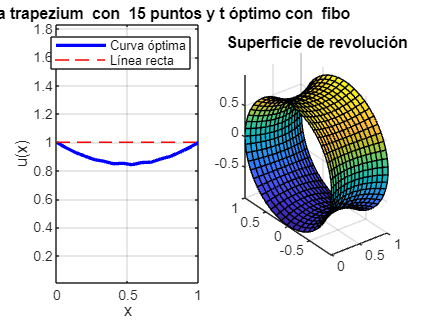

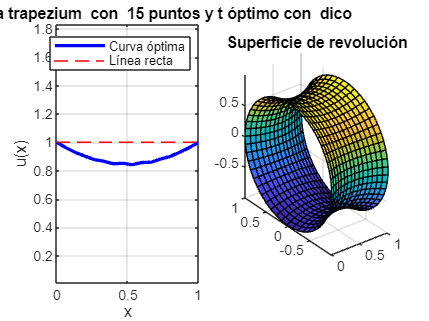

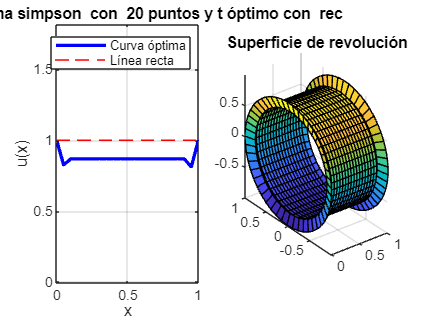

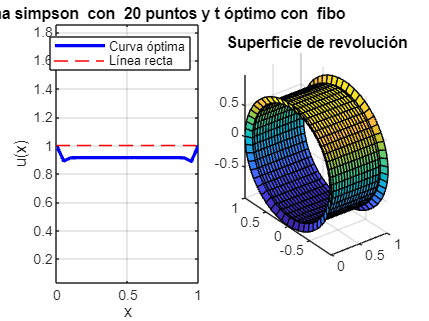

clear, clc
digits(16)
format shortG

% ********************************************************************%
% ******************* BENCHMARK **************************************%
%% Con tolerancia constante y 16 digitos de precisión

max_iter = 10000;   % máximo de iteraciones
tol = 1e-4; % tolerancia máxima
n_values = [15, 20, 25, 50]; % rectas inexactas no tolera n < 15
integral_methods = {'simpson', 'trapezium'};
t_opt_methods = {'rec', 'fibo', 'dico'};

results = table('Size', [numel(n_values)*numel(integral_methods)*numel(t_opt_methods), 5], ...
    'VariableTypes', {'double', 'double', 'double', 'string', 'string'}, ...
    'VariableNames', {'n', 'min_area', 't_opt', 'integral_method', 't_opt_method'});

row = 1;
for n = n_values
    for integral_method = integral_methods
        for t_opt_method = t_opt_methods
            [u_opt, min_area, t_opt] = min_rev_surface(n, max_iter, tol, integral_method{1}, t_opt_method{1});
            results.n(row) = n;
            results.min_area(row) = min_area;
            results.t_opt(row) = t_opt;
            results.integral_method(row) = string(integral_method{1});
            results.t_opt_method(row) = string(t_opt_method{1});
            row = row + 1;
        end
    end
end


disp(results)

    n     min_area      t_opt       integral_method    t_opt_method
    __    ________    __________    _______________    ____________

    15     1.0548     4.2382e-16      "simpson"           "rec"    
    15    0.92462     7.0255e-06      "simpson"           "fibo"   
    15    0.92817     3.1018e-05      "simpson"           "dico"   
    15    0.91296       0.046642      "trapezium"         "rec"    
    15    0.90426       0.041643      "trapezium"         "fibo"   
    15    0.90427       0.041657      "trapezium"         "dico"   
    20    0.98155     4.9136e-16      "simpson"           "rec"    
    20    0.94462     7.0255e-06      "simpson"           "fibo"   
    20    0.94754     3.1018e-05      "simpson"           "dico"   
    20    0.91706       0.030914      "trapezium"         "rec"    
    20    0.9

## Análisis

Si bien el método de Simpson es inherentemente más preciso que el método trapezoidal para funciones suaves ya que aproxima la curva utilizando arcos parabólicos en lugar de segmentos de línea, se observa que en la aproximación del gradiente de Simpson implica términos más complejos, que pueden amplificar los errores numéricos, especialmente para un número pequeño de puntos (n).

Simpson también posee una alta sensibilidad del tamaño del paso, por lo que a menudo se requiere una n puntos más alta para evitar oscilaciones o imprecisiones debido a su dependencia de estimaciones de punto medio y final.

En cuanto al tamaño de paso $t_{optimo}$ para Simpson son signifcativamente más pequeños (entre $10^{-6}  a  10^{-15}$) que para el método trapezoidal. Estos pequeños pasos pueden ralentizar el proceso de optimización y hacerlo más propenso a la inestabilidad numérica.